# **Optimized Hybrid Grey-Fourier Modeling for Precision Landslide Displacement Forecasting**

**Done by: **

**Dhakshin N- CB.SC.U4AIE24313**

**Rohith Ravi - CB.SC.U4AIE24350**

**Sanjay Kumar S - CB.SC.U4AIE24354**

**Akhilan - CB.SC.U4AIE24362**

The raw** E1 sensor displacement readings** are loaded from the **Preonzo Landslide dataset** and NaN values are stripped.

tic
data=readtable("D:\Sem 4\MFC\Project\MFC datasets\Preonzo Landslide dataset.xlsx");
raw_E1=data.E1;
raw_E1=raw_E1(~isnan(raw_E1));
x0=abs(raw_E1);
x0=abs(x0)';

***The Accumulated Generating Operation(AGO) for finding the value of ***$x^{(1)}$***:***

$x^{(1)}(k) = \sum_{i=1}^{k} x^{(0)}(i), \quad k = 1,2,\dots,n
$, where

$x^{(1)}$ is the **1-order Accumulated Generating Operation (1-AGO) Sequence**, calculated as the cumulative sum of $x^{(0)}$ to ***smooth out random fluctuations.***

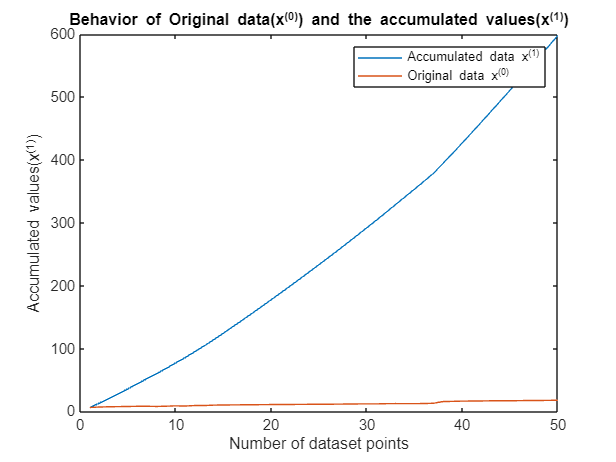

x1=cumsum(x0);
plot(x1(1:50));xlabel("Number of dataset points");ylabel("Accumulated values(x^{(1)})");title("Behavior of Original data(x^{(0)}) and the accumulated values(x^{(1)})");hold on
plot(x0(1:50));
legend("Accumulated data x^{(1)}","Original data x^{(0)}")
hold off

n=size(x0);
n=n(:,2);

#### **WHAT DOES THE "Sliding window" EVEN MEAN?**

The **sliding window, **$\mathbf{x}_w^{(0)} =
\{ x^{(0)}(t-L), \dots, x^{(0)}(t-1) \}
$ represents the most recent $L$ observations used to build the model at time $t$.     

By discarding older data and retaining only this window, the model parameters are continuously updated,*** enabling the metabolic GM(1,1) to adapt to time-varying system behavior***.

L = 5;
x0_hat_meta = zeros(1,n);
x0_hat_meta(1:L) = x0(1:L);
lambda = 0.6;
lambda_r = 0.1;

where, $\lambda_r$ is the **Regularization Parameter**, used in the OLS(Ordinary Least Squares) calculation to prevent overfitting and improve numerical stability and $\mathbf{\lambda_r > 0}

$

a=zeros(1,n);
for t = L+1:n
    x0_win = x0(t-L : t-1); % Sliding window of Velocities
    x1_win = cumsum(x0_win); % Local Displacement

***Background Value Sequence:***

$z^{(1)}(k) = \lambda x^{(1)}(k) + (1-\lambda)x^{(1)}(k-1),
\quad k = 2,3,\dots,n
$, where $\lambda$ is between (0,1), where

$z^{(1)}$: The **Background Value Sequence**, representing the mean of the ***1-AGO sequence at consecutive time steps.***

**1. When **$\lambda$** should be **$0.5$** (Standard/Linear Growth)**

- **The Scenario:** Used when the data sequence has a very stable, low-growth rate.

- **The Reason:** A value of $0.5$ represents the **trapezoidal rule**, which assumes the **data grows linearly between two points**.

- **Estimation:** This is the baseline for **"steady-state"** systems.

**2. When **$\lambda$** should be Less than **$0.5$ $(\lambda < 0.5)$

- **The Scenario:** Used for **high-growth (rapidly accelerating)** sequences.

- **The Reason:** In a rapidly growing exponential curve, the **"area"** or background value is physically closer to the previous point $x^{(1)}(k-1)$ than the current point.

- **Estimation:** If the landslide data shows a sudden "kick" or acceleration, shifting $\lambda$ toward $0.1$ or $0.2$ reduces the overestimation error.

**3. When **$\lambda$** should be Nearest to **$1$ $(\lambda \to 1)$

- **The Scenario:** Used when the data is **slowing down** or approaching a plateau.

- **The Reason:** As the growth curve flattens, the background value should be weighted more heavily toward the most recent observation $x^{(1)}(k)$ to reflect the current state of the system accurately.

- **Estimation:** This is typical for "decelerating" phases in stabilizing slopes.

    z1 = lambda * x1_win(2:end) + (1-lambda) * x1_win(1:end-1);

ans = 0

#### 1. Derivation of Parameter Estimation $\hat{\theta}$

This equation is the **Regularized Least Squares** (Ridge Regression) solution used to find the parameters $a$ and $b$ from the **discrete Grey equation**: $x^{(0)}(k) + az^{(1)}(k) = b$.

For $x^{(0)}$ and $z^{(1)}$ in matrix form, is represented as:

$\mathbf{B} =
\left[
\begin{array}{cc}
- z^{(1)}(2) & 1 \\
- z^{(1)}(3) & 1 \\
\vdots & \vdots \\
- z^{(1)}(n) & 1
\end{array}
\right]
$ and  $\mathbf{Y} =
\left[
\begin{array}{c}
x^{(0)}(2) \\
x^{(0)}(3) \\
\vdots \\
x^{(0)}(n)
\end{array}
\right]
$

- $B$: The **Data Matrix** (Grey Matrix) constructed from the background values $z^{(1)}$.

- $Y$: The **Constant Vector** consisting of the raw data from the second point onwards

    B = [-z1' ones(L-1,1)];

ans = -0.1251

    Y = x0_win(2:end)';

#### Step 1:  We minimize the **Cost Function** $J(\theta)$ with respect to $\theta$, which includes a regularization term $\lambda_r$ to prevent overfitting:


$$$$J(\theta) = \|Y - B\theta\|^2 + \lambda_r\|\theta\|^2$$$$


#### Step 2. By expanding the norms:

Using matrix properties where $$\|A\|^2 = A^\top A$$:


$$$$J(\theta) = (Y - B\theta)^\top (Y - B\theta) + \lambda_r \theta^\top \theta$$$$J(\theta) = (Y^\top - \theta^\top B^\top)(Y - B\theta) + \lambda_r \theta^\top \theta$$$$J(\theta) = Y^\top Y - Y^\top B\theta - \theta^\top B^\top Y + \theta^\top B^\top B\theta + \lambda_r \theta^\top \theta$$$$


#### Step 3: By differentiating with respect to $\theta$:

To find the minimum, we take the partial derivative and set it to zero $$(\frac{\partial J}{\partial \theta} = 0)$$:


$$$$\frac{\partial J}{\partial \theta} = -2B^\top Y + 2B^\top B\theta + 2\lambda_r \theta = 0$$$$


#### Step 4: Solve for $\hat{\theta}$:

Divide by 2 and group the $\theta$ terms:


$$$$(B^\top B + \lambda_r I)\theta = B^\top Y$$$$


Multiply both sides by the inverse $$(B^\top B + \lambda_r I)^{-1}$$:


$$$$\hat{\theta} = (B^\top B + \lambda_r I)^{-1} B^\top Y$$$$
 

    theta = (B'*B + lambda_r*eye(2)) \ (B'*Y);

$\theta$: The **Parameter Vector** $[a, b]^\top$

- $a$: The **Development Coefficient**, which determines the system's growth or decay trend.

- **Example:** If $a$ is a small negative value (e.g., $-0.05$), it tells the model that the landslide is in a **steady-state creep phase**. The slope is moving slowly but consistently. 

- $b$: The **Grey Driving Coefficient**, representing the external influence or constant driving force on the system.

- **Example:** If $b$ is a large positive value, it represents a strong **driving factor**—such as continuous heavy rainfall or a specific soil saturation level that is pushing the ground to move regardless of past movement. 

    a(t) = theta(1);
    b = theta(2);

#### 2. Whitenization Equation:

- The **whitenization equation** in GM(1,1) converts the discrete grey model into a continuous first-order differential equation to describe the system’s evolution.

- It represents the underlying exponential law governing the accumulated sequence $x^{(1)}$.

- By solving this equation, the time response function used for prediction is obtained.


$$\frac{dx^{(1)}(t)}{dt} + a x^{(1)}(t) = b
$$


To solve the Whitenization Equation since it is in the form of Standard Linear ODE form: 

$\frac{dy}{dt} + P(t)y = Q(t)
$ , where 


$$y = x^{(1)}(t), \quad P(t) = a, \quad Q(t) = b
$$


Integrating factor:


$$I(t) = e^{\int a\,dt} = e^{at}
$$


Multiply entire equation by integrating factor(I(t)):


$$e^{at}\frac{dx^{(1)}(t)}{dt} + a e^{at}x^{(1)}(t) = b e^{at}
$$


Convert to total derivative:


$$\frac{d}{dt}\left[x^{(1)}(t)e^{at}\right] = b e^{at}
$$


Integrate both sides: 


$$x^{(1)}(t)e^{at} = \frac{b}{a}e^{at} + C
$$


Solve for $\mathbf x^{(1)}(t)$:

$\hat{x}^{(1)}(k)
=
\left(x^{(1)}(1) - \frac{b}{a}\right)
e^{-a(k-1)} + \frac{b}{a}
$, where

$\hat{x}^{(1)}$: The **Predicted 1-AGO values** generated by the exponential Time Response Function.

Apply initial condition:


$$x^{(1)}(1) = x^{(0)}(1)
$$


*and*


$$C = x^{(0)}(1) - \frac{b}{a}
$$


Final GM(1,1) time response function:


$$\hat{x}^{(1)}(k)
=
\left(x^{(0)}(1) - \frac{b}{a}\right)e^{-a(k-1)} + \frac{b}{a}
$$


$\hat{x}^{(1)}(k)$: This represents the **predicted cumulative displacement** of the landslide at time step $k$


$$\hat{x}^{(0)}(1) = x^{(0)}(1)
$$


 is a fundamental rule for initializing a Grey Model. It means that **the first predicted point must be exactly equal to the first observed data point.**

   x1_hat = (x1_win(1) - b/a(t)) * exp(-a(t) * (0:L-1)) + b/a(t); 

E = 1.0e+05 *

  -5.4559 + 0.0000i  -0.1510 - 1.1566i   0.0430 - 0.5178i  -0.0128 - 0.4186i   0.0744 - 0.2854i  -0.0087 - 0.2531i   0.0464 - 0.2196i   0.0023 - 0.1803i   0.0069 - 0.2054i   0.0038 - 0.1525i  -0.0011 - 0.1634i  -0.0038 - 0.1330i  -0.0256 - 0.1486i   0.0002 - 0.1295i  -0.0159 - 0.1197i  -0.0072 - 0.1103i  -0.0201 - 0.0991i  -0.0084 - 0.1027i  -0.0125 - 0.0860i  -0.0134 - 0.0906i  -0.0052 - 0.0809i  -0.0060 - 0.0814i  -0.0029 - 0.0733i  -0.0076 - 0.0733i   0.0031 - 0.0732i  -0.0032 - 0.0658i  -0.0020 - 0.0699i  -0.0032 - 0.0668i  -0.0041 - 0.0687i  -0.0025 - 0.0596i  -0.0052 - 0.0634i  -0.0002 - 0.0609i  -0.0063 - 0.0559i  -0.0047 - 0.0575i  -0.0084 - 0.0533i  -0.0041 - 0.0546i  -0.0037 - 0.0468i  -0.0063 - 0.0501i  -0.0018 - 0.0455i  -0.0040 - 0.0453i  -0.0010 - 0.0429i  -0.0047 - 0.0426i   0.0007 - 0.0446i  -0.0026 - 0.0387i  -0.0018 - 0.0425i  -0.0009 - 0.0397i  -0.0009 - 0.0414i  -0.0001 - 0.0372i  -0.0035 - 0.0398i   0.0004 - 0.0383i



$$\hat{x}^{(0)}(k) = \hat{x}^{(1)}(k) - \hat{x}^{(1)}(k-1),
\quad k = 2,3,\dots,n
$$


$\hat x^{(0)}$: The **Prediction values** in original units, obtained by calculating the difference between consecutive predicted $\hat{x}^{(1)}$ values.

   x0_hat_meta(t) = x1_hat(end) - x1_hat(end-1);

magE = 1.0e+05 *

    5.4559    1.1664    0.5196    0.4188    0.2949    0.2532    0.2245    0.1803    0.2055    0.1525    0.1634    0.1330    0.1508    0.1295    0.1207    0.1105    0.1012    0.1031    0.0869    0.0915    0.0811    0.0816    0.0733    0.0737    0.0732    0.0659    0.0699    0.0669    0.0689    0.0597    0.0636    0.0609    0.0562    0.0577    0.0539    0.0548    0.0470    0.0505    0.0455    0.0455    0.0429    0.0428    0.0446    0.0388    0.0425    0.0397    0.0414    0.0372    0.0400    0.0383


end
max(a)
min(a)

### **FAST FOURIER TRANSFORM(FFT):**

- We use the ***FFT*** to ***identify and model structured periodic patterns***** in the residual errors** that the GM(1,1) model cannot capture.

- By transforming residuals from the time domain to the frequency domain, FFT allows us to ***extract dominant low-frequency components*** efficiently.

- Adding these components back reduces systematic error and ***improves prediction accuracy*** without altering the core GM model.

## Small example (step by step):

***Step 1: GM captures trend but leaves structured residuals***

Suppose the true data is:


$$x^{(0)} = [10,\ 12,\ 14,\ 16,\ 18,\ 20]$$


A GM(1,1) model captures the ***trend*** and predicts:


$$\hat{x}^{(0)} = [10,\ 11.8,\ 14.2,\ 15.9,\ 18.1,\ 19.8]$$


Now compute the ***residua*****l**:


$$
e = x^{(0)} - \hat{x}^{(0)} = [0,\ 0.2,\ -0.2,\ 0.1,\ -0.1,\ 0.2]$$


These errors are ***not random***; they oscillate.

***Step 2*****: *****FFT reveals periodic structure in residuals***

The residual looks like a ***small oscillation*** ***around zero***.

Applying FFT:


$$E=FFT(e)$$


We observe:

- One **dominant low-frequency peak **indicates a **repeating pattern** in the residuals

FFT converts “hard-to-see oscillations” in time domain into ***clear frequency components***.

***Step 3: Reconstruct residual and improve prediction***

Using only the dominant FFT component, we reconstruct:


$$\hat{e} = [0,\ 0.18,\ -0.18,\ 0.12,\ -0.12,\ 0.18]$$


Now correct the prediction:


$$\hat{x}^{(0)}_{\text{final}} = \hat{x}^{(0)} + \hat{e}$$


***Step4*****:** the ***Result***


$$\hat{x}^{(0)}_{\text{final}} \approx [10,\ 12,\ 14,\ 16,\ 18,\ 20]$$


Now, the** systematic error is removed**, **accuracy improves without changing the GM model**.

x0=x0(:)';
x0_hat_meta=x0_hat_meta(:)';
res_meta=x0-x0_hat_meta;
E = fft(res_meta)
magE = abs(E)

The reason why we have chosen the value of K as 3 is:

        The Preonzo landslide has well-documented physical cycles that drive periodic displacement patterns:

- **Annual seasonal cycle** — freeze-thaw, snowmelt, rainfall seasonality (1 dominant frequency)

- **Sub-annual cycle** — typically a 6-month harmonic of the above (1 frequency)

- **Short-term atmospheric/rainfall cycle** — weeks to months (1 frequency)

That becomes a total of 3 frequencies.

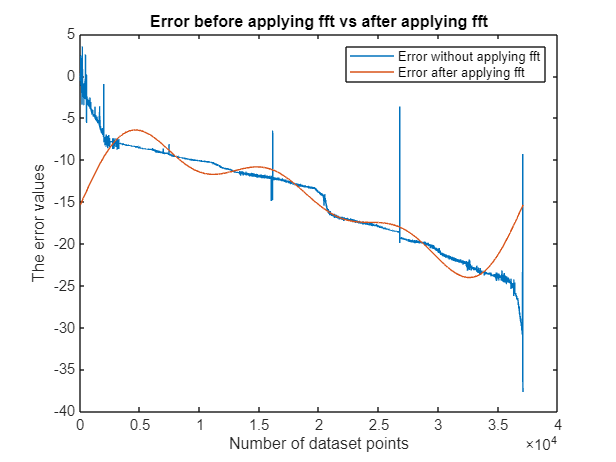

K=3;
[~, idx] = sort(magE(2:floor(n/2)), 'descend');
idx = idx(1:K) + 1;

E_filt = zeros(size(E));
E_filt(1) = E(1);
E_filt(idx) = E(idx);
E_filt(n-idx+2) = E(n-idx+2);
res_hat_meta = real(ifft(E_filt));

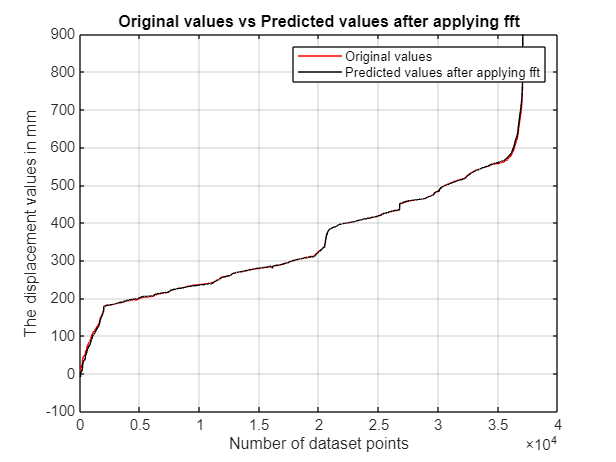

x0_hat_meta_final = x0_hat_meta + res_hat_meta;
plot(res_meta);hold on
plot(res_hat_meta);legend("Error without applying fft","Error after applying fft");
xlabel("Number of dataset points");ylabel("The error values");title("Error before applying fft vs after applying fft");
hold off;
err_meta = x0 - x0_hat_meta_final;
plot(x0,"r");hold on

plot(x0_hat_meta_final,"k");legend("Original values","Predicted values after applying fft");
xlabel("Number of dataset points");ylabel("The displacement values in mm");
title("Original values vs Predicted values after applying fft");
hold off
grid on

### ***The Risk Index Equation:***

This is the primary formula that combines our prediction accuracy with the physical acceleration of the landslide.


$$R(k) = \left( \frac{|x^{(0)}(k) - \hat{x}^{(0)}_{final}(k)|}{x^{(0)}(k)} \times \omega_{1} \right) + (|a_k| \times \omega_{2})$$


Where:

- $x^{(0)}(k)$: The actual displacement measured by the sensor at time $k$.

- $\hat{x}^{(0)}_{final}(k)$: The hybrid metabolic prediction (Grey Model + FFT correction).

- $a_k$: The development coefficient (acceleration) from the current metabolic window.

- $\omega_{1}$: The error sensitivity weight (set to **100**).

- $\omega_{2}$: The acceleration sensitivity weight (set to **5**).

risk_values = ones(1,n)*1.75;    
hazard_level = strings(1,n); 
hazard_level(:) = "No Warning";

RC = 0.001;
RT = 1.75;  
for k = 2769:n
    num = abs(x0(k) - x0_hat_meta_final(k));
    den = x0(k);
    p_i = num / den;
    accel_factor = abs(a(k));            
    risk_values(k) = (p_i * 100) + (accel_factor * 5);
    if risk_values(k) > RT
        hazard_level(k) = "Advanced Warning";
    else
        hazard_level(k) = "Safe";
    end
end

% Limit risk value only for visualization stability
risk_values_1 = min(risk_values, 20);
risk_values_2=risk_values_2(1:n);
risk_values_3=risk_values_3(1:n);

**The global risk value(After calculating for all the sensors):**

risk_values=(risk_values+risk_values_2+risk_values_3)/3;

#### **Risk value for the E1 sensor:**

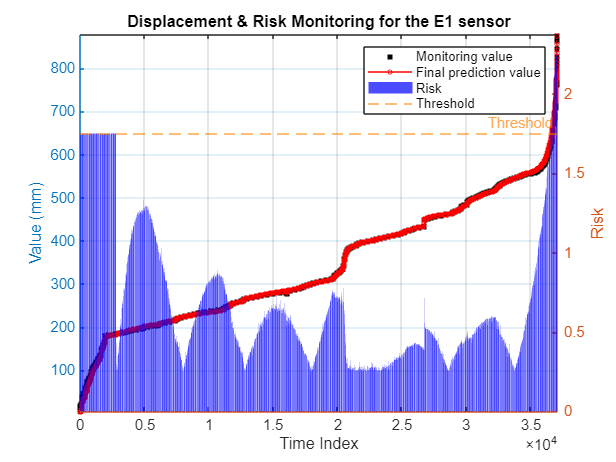

figure;

yyaxis left
plot(x0, 'ks', 'MarkerSize', 4, 'MarkerFaceColor', 'k');
hold on
plot(x0_hat_meta_final, 'r-o', 'MarkerSize', 3);
ylabel('Value (mm)');
ylim([min(x0)-2, max(x0)+2]);

yyaxis right
bar(risk_values_1, 'FaceColor', 'b', 'FaceAlpha', 0.7);
ylabel('Risk');
ylim([0, max(risk_values)*1.2]);

hold on
yline(RT, '--', 'Threshold', 'Color', [1 0.5 0]);

xlabel('Time Index');
title('Displacement & Risk Monitoring for the E1 sensor');

legend('Monitoring value', ...
       'Final prediction value', ...
       'Risk', ...
       'Threshold');

grid on

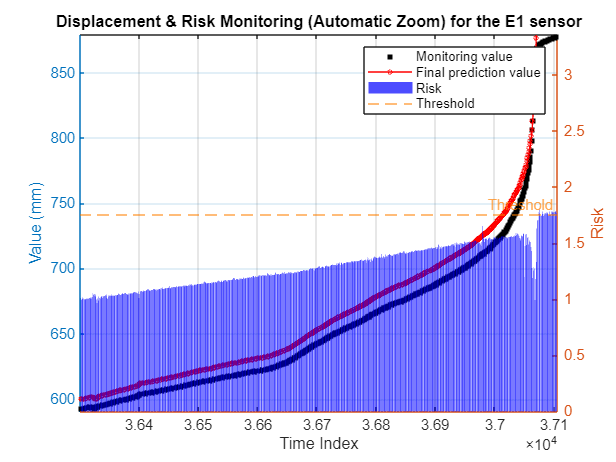

idx = 36302:37105;   

% Safety check (prevents index overflow)
idx = idx(idx <= n);

figure;

yyaxis left
plot(idx, x0(idx),'ks','MarkerSize',4,'MarkerFaceColor','k'); hold on
plot(idx, x0_hat_meta_final(idx),'r-o','MarkerSize',3);
ylabel('Value (mm)');
ylim([min(x0(idx))-2 max(x0(idx))+2])

yyaxis right
bar(idx, risk_values(idx),'FaceColor','b','FaceAlpha',0.7);
ylabel('Risk');
ylim([0 max(risk_values_1(idx))*1.2])

hold on
yline(RT,'--','Threshold','Color',[1 0.5 0]);

xlabel('Time Index');
title('Displacement & Risk Monitoring (Automatic Zoom) for the E1 sensor');
legend('Monitoring value','Final prediction value','Risk','Threshold');

grid on

### The Original Combined Displacement & Global Risk Plot(With all values considered)

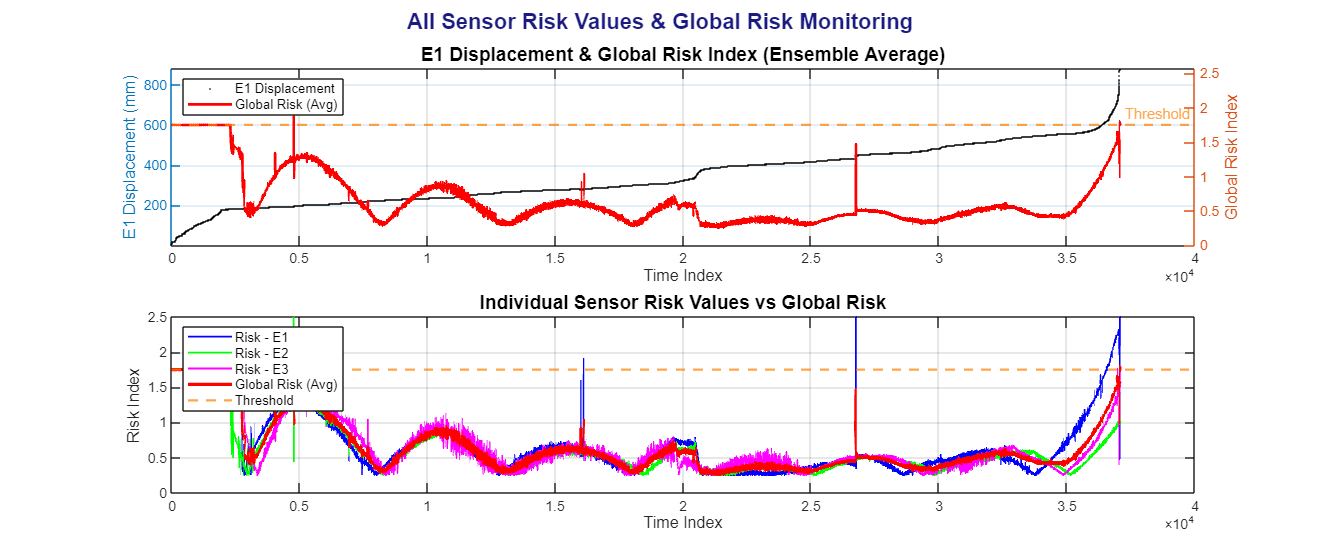

%% ------------------ CLEAN ALL-SENSOR + GLOBAL RISK PLOT ------------------

figure('Position', [100, 100, 1200, 500]);

% ========== TOP SUBPLOT: Displacement + Global Risk ==========
subplot(2,1,1);

yyaxis left
plot(x0, 'k.', 'MarkerSize', 2);
ylabel('E1 Displacement (mm)', 'FontSize', 11);
ylim([min(x0)-5, max(x0)+5]);

yyaxis right
plot(risk_values, 'r-', 'LineWidth', 1.8);
hold on
yline(RT, '--', 'Color', [1 0.5 0], 'LineWidth', 1.5, 'Label', 'Threshold');
ylabel('Global Risk Index', 'FontSize', 11);
ylim([0, max(risk_values)*1.3]);

xlabel('Time Index', 'FontSize', 11);
title('E1 Displacement & Global Risk Index (Ensemble Average)', 'FontSize', 13, 'FontWeight', 'bold');
legend('E1 Displacement', 'Global Risk (Avg)', 'Location', 'northwest', 'FontSize', 9);
grid on;

% ========== BOTTOM SUBPLOT: Individual Sensor Risks Separated ==========
subplot(2,1,2);

plot(risk_values_1, 'b-', 'LineWidth', 1.2);
hold on
plot(risk_values_2, 'g-', 'LineWidth', 1.2);
plot(risk_values_3, 'm-', 'LineWidth', 1.2);
plot(risk_values,   'r-', 'LineWidth', 2.2);
yline(RT, '--', 'Color', [1 0.5 0], 'LineWidth', 1.5);

xlabel('Time Index', 'FontSize', 11);
ylabel('Risk Index', 'FontSize', 11);
title('Individual Sensor Risk Values vs Global Risk', 'FontSize', 13, 'FontWeight', 'bold');
legend('Risk - E1', 'Risk - E2', 'Risk - E3', 'Global Risk (Avg)', 'Threshold', ...
       'Location', 'northwest', 'FontSize', 9);
ylim([0, 2.5]);
grid on;

sgtitle('All Sensor Risk Values & Global Risk Monitoring', 'FontSize', 15, 'FontWeight', 'bold', 'Color', [0.1 0.1 0.5]);

###  E1 Displacement & Global Risk Index (Ensemble Average)

### **The zoomed graph during the time of the occurrence of the landslide is shown below:**

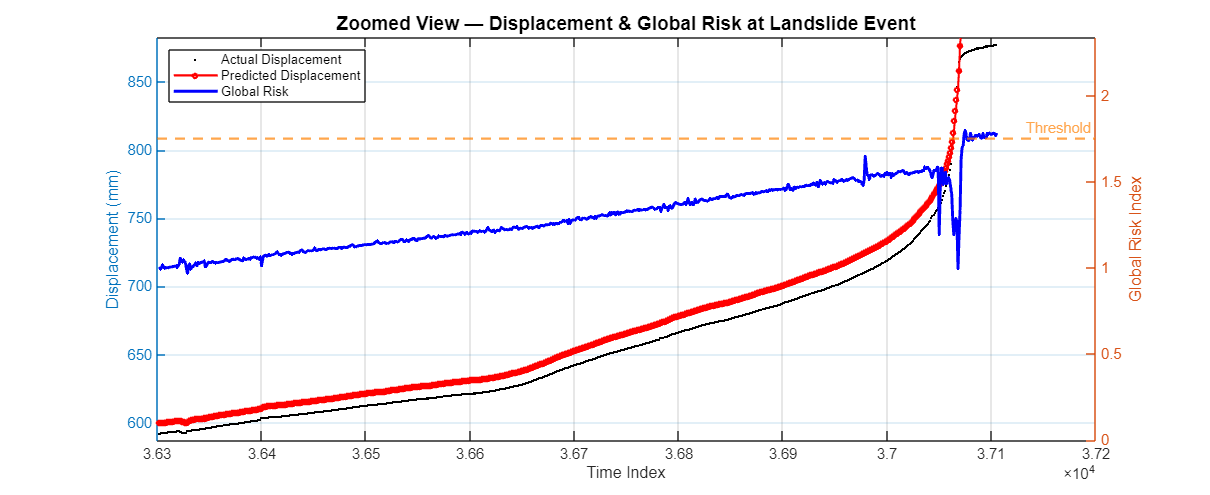

%% ------------------ CLEAN ZOOMED PLOT (Landslide Event) ------------------

zoom_idx = 36302:37105;
zoom_idx = zoom_idx(zoom_idx <= n);

figure('Position', [100, 100, 1100, 450]);

yyaxis left
plot(zoom_idx, x0(zoom_idx), 'k.', 'MarkerSize', 4);
hold on
plot(zoom_idx, x0_hat_meta_final(zoom_idx), 'r-o', 'MarkerSize', 3, 'LineWidth', 1.4);
ylabel('Displacement (mm)', 'FontSize', 11);
ylim([min(x0(zoom_idx))-5, max(x0(zoom_idx))+5]);

yyaxis right
plot(zoom_idx, risk_values(zoom_idx), 'b-', 'LineWidth', 2);
hold on
yline(RT, '--', 'Color', [1 0.5 0], 'LineWidth', 1.5, 'Label', 'Threshold');
ylabel('Global Risk Index', 'FontSize', 11);
ylim([0, max(risk_values(zoom_idx))*1.3]);

xlabel('Time Index', 'FontSize', 11);
title('Zoomed View — Displacement & Global Risk at Landslide Event', 'FontSize', 13, 'FontWeight', 'bold');
legend('Actual Displacement', 'Predicted Displacement', 'Global Risk', 'Location', 'northwest', 'FontSize', 9);
grid on;

toc

Elapsed time is 3.525388 seconds.


Total time elapsed by all the three codes: `3.525388+2.323202+3.241025= 9.089615 seconds.`